# Illustrating Milnor's proof of Brouwer's fixed point theorem in $2$ dimensions

The process is as follows:

- Generate a vector field $V$ in $2$d: $x,y,u,v$ where $(x,y)$ is the position and $(u,v)$ is the tangent vector. 

- Make the tangent vectors point outward on the boundary and get a new vector field $W$

- Using stereogrphic projections of the points $(x,y)$ and the tangent vectors $(u,v)$, get a vector field on the sphere. 

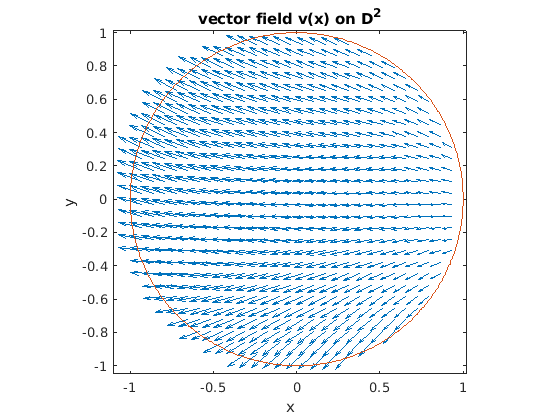

%roughly square root of the number of data points
num_dat= 30;

%%1. Generating a vector field 
%meshgrid of points in the square [-1,1]x[-1,1]
[x,y] = meshgrid(linspace(-1,1,num_dat),linspace(-1,1,num_dat));
%logical statement specifying a disk or radius 1
logic_disk= x.^2+y.^2<=1;
%restricting the meshgrid to the disk
x= x(logic_disk);
y= y(logic_disk);
%defining the tangent vectors smoothly based on the points
u= -(sin(x+1.2)+sin(y+1.5))+x;
v= -(sin(x+1.2)-sin(y+1.5))+y;
%visualizing the vector field
quiver(x,y,u,v,1.5);
axis equal;
hold on;
%drawing a circle of radius 1
fimplicit(@(s,t) s.^2+t.^2-1);
axis equal;
xlim([-1.1,1.02]);
ylim([-1.05,1.01]);
xlabel('x');ylabel('y');
title('vector field v(x) on D^2');
print('-dpng','-r200','fieldvx');
hold off;

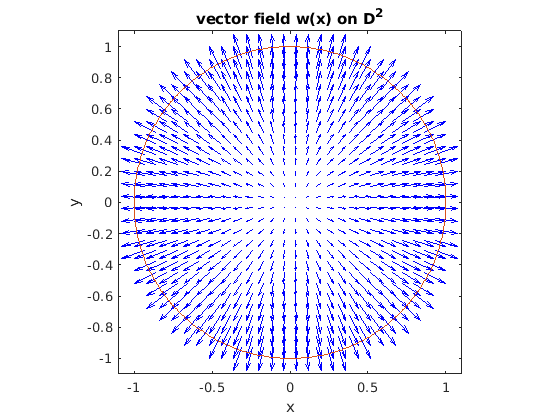


%%2. Making the tangent vectors point outward on the boundary
Wx= [x, y]- ((1-dot([x, y],[x, y],2))./(1-dot([x, y],[u, v]))).*[u, v];
%get the outward vectors
u_out= Wx(:,1);
v_out= Wx(:,2);
%visualizing the vector field
figure
quiver(x,y,u_out,v_out,1.5,'blue');
axis equal;
hold on;
%drawing a circle of radius 1
fimplicit(@(s,t) s.^2+t.^2-1);
axis equal;
xlim([-1.1,1.1]);
ylim([-1.1,1.1]);
xlabel('x');ylabel('y');
title('vector field w(x) on D^2');
print('-dpng','-r200','fieldwx');
hold off;

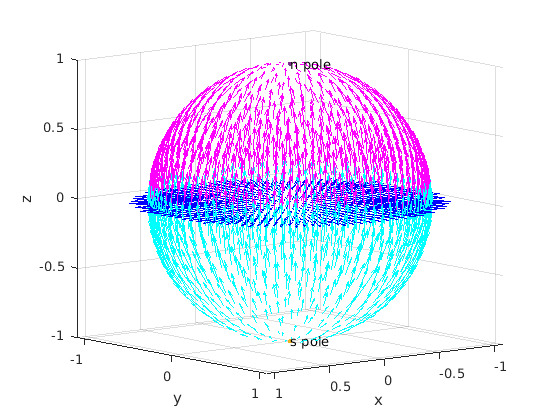


%%3. Projecting the vector field onto the sphere by stereographic proj

%%%bottom hemisphere
%stereographic projections
[x_bot, y_bot, z_bot]= ste_pos(x,y,'s');
[u_bot, v_bot, w_bot]= ste_tan(x,y,u_out, v_out, 's');

figure('Name','plot_final')
quiver3(x_bot,y_bot,z_bot,u_bot,v_bot,w_bot,1.5,'c');
axis equal;
hold on
xlabel('x');ylabel('y');zlabel('z');
%%%top hemisphere
%stereographic projections
[x_top, y_top, z_top]= ste_pos(x,y, 'n');
[u_top, v_top, w_top]= ste_tan(x,y,u_out, v_out,'n');

%plotting the vector field
quiver3(x_top,y_top,z_top,u_top,v_top,w_top,1.5,'m');
axis equal;
hold on
%plotting a sphere
%fimplicit3(@(t,s,r) t.^2+s.^2+r.^2-1,'EdgeColor','none','FaceAlpha',.1);
%axis equal;

%marking the poles
scatter3(0,0,-1,'.');
text(0,0,-1,'s pole');

scatter3(0,0,1,'.');
text(0,0,1,'n pole');

%plotting the original vector field w(x) on the z=0 plane
quiver3(x,y,zeros(size(x)),u_out,v_out,zeros(size(u_out)),1.5,'blue');

axis equal;
hold off
xlabel('x');ylabel('y');zlabel('z');
%viewing angle of the sphere
v0 = [1 1.25 0.25];
[caz,cel] = view(v0);
print('-dpng','-r200','plot_final');

## Functions

function [x_outp, y_outp, z_outp] = ste_pos(x_inp,y_inp,pole_)
    %stereographic projection for the position of the points on the disk
    %the disk is located at z=0 
    %inputs: x_inp y_inp coordinates of a point on the disk
    %        pole_ is a character 's' or 'n', specifying for which pole the
    %        projection is happening.
    %outputs: the coordinates of the image of the map. 
    if pole_== 'n'
        n=1;
    elseif pole_== 's'
        n=0;
    end
    x_outp= 2*x_inp./(x_inp.^2+y_inp.^2+1);
    y_outp= 2*y_inp./(x_inp.^2+y_inp.^2+1);
    z_outp= ((-1)^n)*(x_inp.^2+y_inp.^2-1)./(x_inp.^2+y_inp.^2+1);
end

function [x_outp, y_outp, z_outp] = ste_tan(x_inp,y_inp,u_inp,v_inp, pole_)
    %stereographic projection for the tangent vectors (vector field) on the disk
    %the disk is located at z=0 
    %inputs: x_inp y_inp coordinates of a point on the disk, u_inp v_inp
    %the components of the tangent vector at x_inp y_inp of the disk
    %        pole_ is a character 's' or 'n', specifying for which pole the
    %        projection is happening.
    %outputs: the coordinates of the image tangent vector of the map. 
     if pole_== 'n' 
        n=1;
     elseif pole_== 's'
        n=0;
     end
     
    x_outp= ((-1)^n)*((2*(-x_inp.^2+y_inp.^2+1)).*u_inp -(4*x_inp.*y_inp) ...
        .*v_inp)./(x_inp.^2+y_inp.^2+1).^2;
    y_outp= ((-1)^n)*((-4*x_inp.*y_inp).*u_inp+ (2*(x_inp.^2-y_inp.^2+1)) ...
        .*v_inp)./(x_inp.^2+y_inp.^2+1).^2;
    z_outp= ((4*x_inp).*u_inp+ (4*y_inp).*v_inp)./(x_inp.^2+y_inp.^2+1).^2;
end



